## The Fibonacci Sequence

Fibonacci posed a theoretical problem based on the growth of a population of rabbits starting from a single newborn male and female pair. The assumptions are:

- every month each pair (male-female) pf rabbits mate, and the next month a pair (male-female) of newborn rabbits will be born.

- offspring then take one month to mature before they start reporducing.

- rabbits do not die.

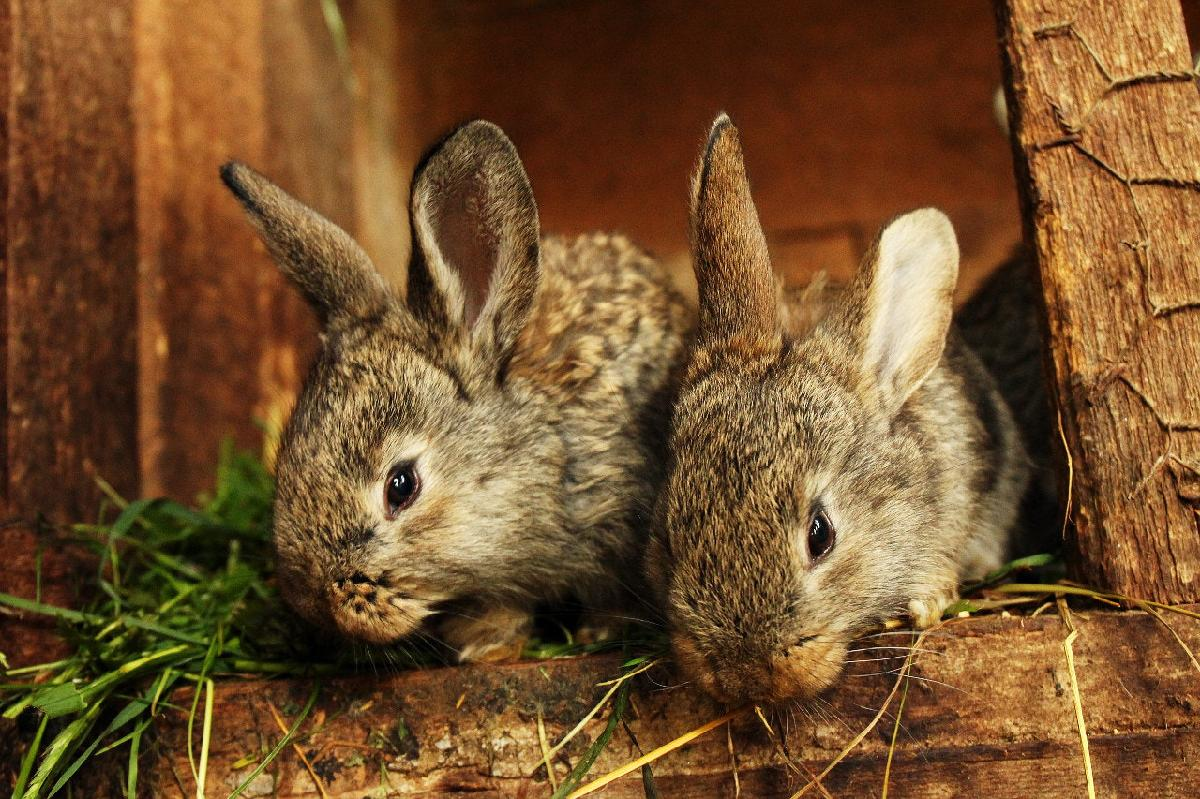

Month 1: 1 newborn pair (total 1 pair)

Month 2: 1 adult pair (total 1 pair)

Month 3: 1 adult pair, 1 newborn pair (total 2 pairs)

Month 4: 2 adult pairs, 1 newborn pair (total 3 pairs)

Month 5: 3 adult pairs, 2 newborn pairs (total 5 pairs)

Month 6: 5 adult pairs, 3 newborn pairs (total 8 pairs)

Let's do this in MATLAB:

%  month 1
% starts with 1 newborn pair
m1_newborn = 1;
m1_adults = 0;
m1_total = m1_newborn + m1_adults;
m1_total

m1_total = 1


%  month 2
% each pair of adults produce 1 newborn pair
m2_newborn = m1_adults;
% each newborn pair mature to adults
m2_adults = m1_adults + m1_newborn;
% find total in month 2
m2_total = m2_adults + m2_newborn;
m2_total

m2_total = 1


%  month 3
% each pair of adults produce 1 newborn pair
m3_newborn = m2_adults;
% each newborn pair mature to adults
m3_adults = m2_adults + m2_newborn;
% find total in month 2
m3_total = m3_adults + m3_newborn;
m3_total

m3_total = 2


%  month 4
% each pair of adults produce 1 newborn pair
m4_newborn = m3_adults;
% each newborn pair mature to adults
m4_adults = m3_adults + m3_newborn;
% find total in month 2
m4_total = m4_adults + m4_newborn;
m4_total

m4_total = 3


%  month 5
% each pair of adults produce 1 newborn pair
m5_newborn = m4_adults;
% each newborn pair mature to adults
m5_adults = m4_adults + m4_newborn;
% find total in month 2
m5_total = m5_adults + m5_newborn;
m5_total

m5_total = 5

This sequence can be written mathematically as an iterative formula (meaning a calculation that is carried out as a sequence of steps). 

We define $R_{i\;}$to represent the number of rabbits after $i$ months, and specify the first terms:

$R_1 =1$, $R_2 =1$

We can then calculate the subsequent terms using:


$$R_{i\;} =R_{i-1} +R_{i-2}$$


We can code this iteratively in MATLAB using a loop. First we create an empty array to store the sequence.

results = zeros(1,6)

results =      0     0     0     0     0     0


Next we specify first two numbers in the sequence:

results(1) = 1;
results(2) = 1;
results

results =      1     1     0     0     0     0


Then we use a loop to step forward and calculate the sequence:

for i=3:6
    results(i)=results(i-1)+results(i-2);
end
results

results =      1     1     2     3     5     8


After 6 months there would be 8 rabbits!

You can read more about the Fibonacci sequence at: 

[http://www.maths.surrey.ac.uk/hosted-sites/R.Knott/Fibonacci/fib.html](http://www.maths.surrey.ac.uk/hosted-sites/R.Knott/Fibonacci/fib.html)